rng(1)


lambda = 0.8;  % 泊松分布参数（到达率）
mu = 2;       % 指数分布参数（服务率）
numCustomers = 200;  % 总顾客数

interArrivalTime = exprnd(1/lambda, 1, numCustomers);  % 到达时间间隔
serviceTime = exprnd(1/mu, 1, numCustomers);  % 服务时间

arrivalTime = cumsum(interArrivalTime);  % 到达时间
departureTime = zeros(1, numCustomers);  % 离开时间

queueLength = 0;  % 队列长度
numInQueue = zeros(1, numCustomers);  % 队列中的顾客数

for i = 1:numCustomers
    if i == 1
        departureTime(i) = arrivalTime(i) + serviceTime(i);
        queueLength = 0;
    else
        if arrivalTime(i) < departureTime(i-1)
            queueLength = queueLength + 1;
        else
            queueLength = max(queueLength - 1, 0);
        end
        departureTime(i) = max(arrivalTime(i), departureTime(i-1)) + serviceTime(i);
    end
    numInQueue(i) = queueLength;
end

%averageQueueLength = mean(numInQueue);  % 平均队列长度
%averageWaitTime = mean(numInQueue ./ lambda);  % 平均等待时间

fprintf('平均队列长度: %.2f\n', averageQueueLength);

平均队列长度: 0.27


fprintf('平均等待时间: %.2f\n', averageWaitTime);

平均等待时间: 0.89


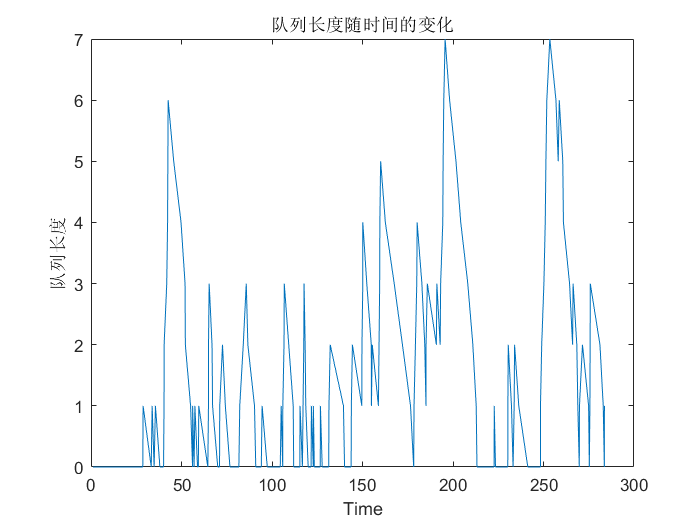


% 绘制队列长度随时间的变化图
figure;
plot(cumsum(interArrivalTime), numInQueue);
xlabel('Time');
ylabel('队列长度');
title('队列长度随时间的变化');

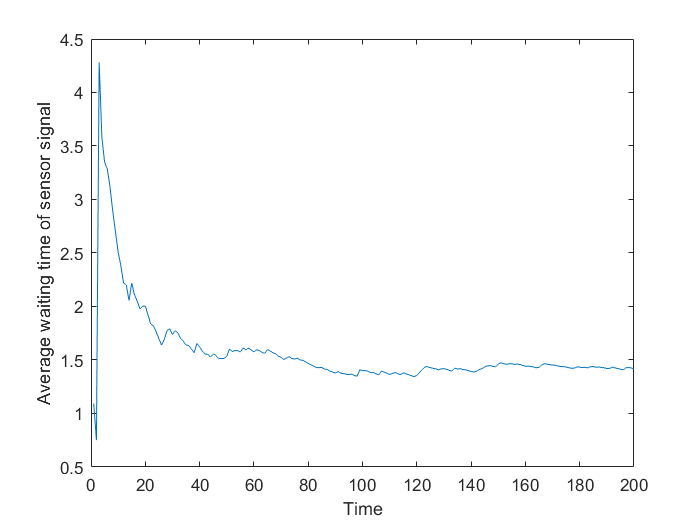


b = cumsum(interArrivalTime);
for i = 1:numCustomers
    b(i) = b(i) / i;
end
% 绘制队列长度随时间的变化图
figure;
plot(1:numCustomers,b);
xlabel('Step');
ylabel('Average waiting time of sensor signal');

%title('The variation of average waiting time of sensor signals over time');